From the assigment1 subquestion(c), create matrices 

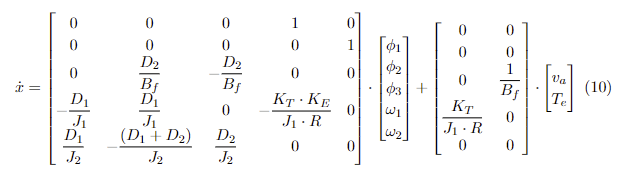

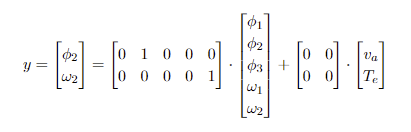

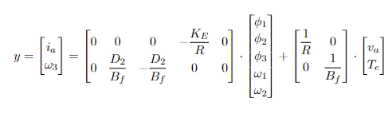

clc
clear
syms R D_1 
KE = 1e-1;
KT = 1e-1;
J1 = 1e-5;
J2 = 4e-5;
Bf = 2e-3

Bf = 0.0020

D_2 = 2;

C1 = [0 1 0 0 0; 0 0 0 0 1];
D1 = [0 0; 0 0];
C2 = [0 0 0 (-KE/R) 0; 0 (D_2/Bf) (-D_2/Bf) 0 0];
D2 = [(1/R) 0; 0 (1/Bf)];
A = [0 0 0 1 0;
     0 0 0 0 1;
     0 (D_2/Bf) -(D_2/Bf) 0 0;
     -(D_1/J1) (D_1/J1) 0 -(KT*KE/J1/R) 0;
     (D_1/J2) -((D_1+D_2)/J2) (D_2/J2) 0 0];
B = [0 0;
     0 0;
     0 (1/Bf);
     (KT/J1/R) 0;
     0 0];

Those above are the foundation of all

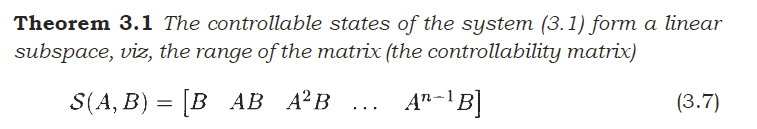

 i = 0;
%  S = cell(100,1)
Mcon = rref([B A*B A^2*B A^3*B])

$$Mcon = \left(\begin{array}{cccccccc} 1 & 0 & 0 & 0 & -100000\,D_{1} & 0 & \frac{100000000\,D_{1}}{R} & 250000000\,D_{1}\,R\\ 0 & 1 & 0 & 0 & \frac{10000\,D_{1}}{R} & 0 & -\frac{10000000\,D_{1}}{R^{2}} & -25000000\,D_{1}\\ 0 & 0 & 1 & 0 & -\frac{1000}{R} & 0 & -\frac{100000\,\left(D_{1}\,R^{2}-10\right)}{R^{2}} & 0\\ 0 & 0 & 0 & 1 & \frac{10\,D_{1}}{R} & 0 & \frac{10000\,D_{1}\,\left(R-1\right)}{R^{2}} & -25000\,D_{1}-50000\\ 0 & 0 & 0 & 0 & 0 & 1 & \frac{10\,D_{1}}{R} & -1000 \end{array}\right)$$

Mob1 = rref([C1; C1*A; C1*A^2; C1*A^3])

$$Mob1 = \left(\begin{array}{ccccc} 1 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

Mob2 = rref([C2; C2*A; C2*A^2; C2*A^3])

$$Mob2 = \left(\begin{array}{ccccc} 1 & 0 & -1 & 0 & 0\\ 0 & 1 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

%  S(1)=Bf;
%  while i<n
%     i = i + 1;
%     S=[S A^i*Bf]
%  end


D_1 = 10

D_1 = 10

R = 1

R = 1

rref(subs(Mcon))% use subs function to take the parameter into Matrix

$$ans = \left(\begin{array}{cccccccc} 1 & 0 & 0 & 0 & -1000000 & 0 & 1000000000 & 2500000000\\ 0 & 1 & 0 & 0 & 100000 & 0 & -100000000 & -250000000\\ 0 & 0 & 1 & 0 & -1000 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 100 & 0 & 0 & -300000\\ 0 & 0 & 0 & 0 & 0 & 1 & 100 & -1000 \end{array}\right)$$

% This way is hand control, too stupid
% fsurf(Mcon,[xmin,xmax,ymin,ymax])

% f1 = @(R,D_1) rank(Mcon)
% fsurf(f1,[0 1000 -500 500])
% hold on